# Standard deviation analysis

We investigate the influence of number of spheroids used in an assay and choosed to study the toxicity of A1155463 against the two cell lines H1975 and HCC872. This combination was choosen since HCC872 is insensitive to the drug shile H1975 is not. Check significance instead!! Do it with OVCAR8 + paxlitaxel och anna drog. Caspace AUC

if exist("via_HHC872", 'var') == 0
    via_H1975   = readtable('TMRM_specific viability/Specific_viability_TMRM_BR_H1975.csv');
    via_HHC872  = readtable('TMRM_specific viability/Specific_viability_TMRM_BR_HHC827.csv');
    cas_OVCAR8  = readtable('Caspase_Total Apoptosis/Caspase_BR_OVCAR8.xlsm');
    cas_HCC872  = readtable('Caspase_Total Apoptosis/Caspase_BR_HHC827.csv');
    rfp_2d      = readtable("RFP and Tubulin titration/RFP_2 exp grouped.csv");
    tubulin_2d  = readtable("RFP and Tubulin titration/Results_Tubulin_Grouped.xlsm");
  
end


rng default

h19_24  = str2double(via_H1975{7, 39:74})./1000;
h19_48  = str2double(via_H1975{14, 39:74})./1000;
hcc_24  = str2double(via_HHC872{7, 39:74})./1000;
hcc_48  = str2double(via_HHC872{14, 39:74})./1000;

rfp1    = str2double(regexprep(rfp_2d{:,2:2:32}, ',','.'));
rfp2    = str2double(regexprep(rfp_2d{:,3:2:33}, ',','.'));
tub_0   = log(tubulin_2d{1,2:end});
tub_02  = log(tubulin_2d{2,2:end});
tub_2   = log(tubulin_2d{3,2:end});
tub_20  = log(tubulin_2d{4,2:end});

time    = [0 1 4 8 12 16 20 24 28 32 36 40 44 48];

%ovc_all     = log(cas_OVCAR8{:,3:end});
%ovc_all     = str2double(regexprep(cas_HCC872{:,3:end}, ',','.'));
ovc_all     = log(str2double(regexprep(cas_HCC872{:,3:end}, ',','.')));
ovc_totAp   = trapz(time, ovc_all,1);
ovc_dmso    = ovc_totAp(1:36);
ovc_a11     = ovc_totAp(37:72);
ovc_gef     = ovc_totAp(73:108);
ovc_pax     = ovc_totAp(109:144);
% ovc_dmso    = log(ovc_totAp(1:36));
% ovc_a11     = log(ovc_totAp(37:72));
% ovc_gef     = log(ovc_totAp(73:108));
% ovc_pax     = log(ovc_totAp(109:144));


With the viability data loaded, the mean value and standard deviation values are created for 1 up to 36 spheroids (20 random permutations each).

numObs      = 500;
lowNumSph   = 3;
highNumSph  = 36;

std_h19_24  = zeros(36,numObs);
std_h19_48  = zeros(36,numObs);
std_hcc_24  = zeros(36,numObs);
std_hcc_48  = zeros(36,numObs);

mean_h19_24 = zeros(36,numObs);
mean_h19_48 = zeros(36,numObs);
mean_hcc_24 = zeros(36,numObs);
mean_hcc_48 = zeros(36,numObs);

p_dmso_a11  = zeros(36,numObs);
p_dmso_gef  = zeros(36,numObs);
s_dmso_pax  = zeros(36,numObs);
s_dmso_a11  = zeros(36,numObs);
s_dmso_gef  = zeros(36,numObs);
n_dmso_pax  = zeros(36,numObs);
n_dmso_a11  = zeros(36,numObs);
n_dmso_gef  = zeros(36,numObs);
p_dmso_pax  = zeros(36,numObs);
p_a11_gef   = zeros(36,numObs);
p_a11_pax   = zeros(36,numObs);
p_gef_pax   = zeros(36,numObs);

pt_dmso_a11 = zeros(36,numObs);
pt_dmso_gef = zeros(36,numObs);
pt_dmso_pax = zeros(36,numObs);


pt_3_10     = zeros(36,numObs);
pt_4_7      = zeros(36,numObs);
pt_8_9      = zeros(36,numObs);
pt_2_14     = zeros(36,numObs);
pt_12_15    = zeros(36,numObs);
pt_1_16     = zeros(36,numObs);

ptub_33_24  = zeros(36,numObs);
ptub_23_14  = zeros(36,numObs);
ptub_33_43  = zeros(36,numObs);
ptub_33_34  = zeros(36,numObs);
ptub_23_24  = zeros(36,numObs);
ptub_43_44  = zeros(36,numObs);

ptub_11_12  = zeros(36,numObs);
ptub_11_21  = zeros(36,numObs);
ptub_11_22  = zeros(36,numObs);
ptub_22_33  = zeros(36,numObs);
ptub_11_33  = zeros(36,numObs);
ptub_23_33  = zeros(36,numObs);
ptub_21_22  = zeros(36,numObs);


pAnova      = zeros(36,numObs);


for i = lowNumSph:highNumSph
    for j = 1:numObs
        
        
        perm    = randi(36,1,i);
        perm2   = randi(36,1,i);
        perm3   = randi(36,1,i);
        perm4   = randi(36,1,i);
        perm5   = randi(36,1,i);
        perm6   = randi(36,1,i);
        
%         if ismember(30, perm4) 
%             ind_temp    = find(perm4 == 30);
%             perm4(ind_temp)  = 31;
%         end
        
%         if ismember(6, perm) 
%             ind_temp    = find(perm == 6);
%             perm(ind_temp)  = 7;
%         end
%         
%         if ismember(18, perm) 
%             ind_temp    = find(perm == 18);
%             perm(ind_temp)  = 19;
%         end
%         if ismember(30, perm) 
%             ind_temp    = find(perm == 30);
%             perm(ind_temp)  = 31;
%         end
        
        statData            = [ovc_dmso(perm2)' ovc_a11(perm)' ovc_gef(perm3)' ovc_pax(perm4)'];
        group               = [1,2,3,4];
        
        std_h19_24(i,j)     = std(h19_24(perm));
        std_h19_48(i,j)     = std(h19_48(perm));
        std_hcc_24(i,j)     = std(hcc_24(perm));
        std_hcc_48(i,j)     = std(hcc_48(perm));
        
        mean_h19_24(i,j)    = mean(h19_24(perm));
        mean_h19_48(i,j)    = mean(h19_48(perm));
        mean_hcc_24(i,j)    = mean(hcc_24(perm));
        mean_hcc_48(i,j)    = mean(hcc_48(perm));
        
         [p_a, ~, stats]    = anova1(statData,group,"off");
        p                   = dunnett(stats);
        p_dmso_a11(i,j)     = p(2);
        p_dmso_gef(i,j)     = p(3);
        p_dmso_pax(i,j)     = p(4);
        pAnova(i,j)         = p_a;
        
      
%        [p_a, ~, stats]     = kruskalwallis(statData,group,"off");
%         c                   = multcompare(stats,"CType","hsd","Display","off");
%         p_dmso_a11(i,j)     = c(1,6);
%         p_dmso_gef(i,j)     = c(2,6);
%         p_dmso_pax(i,j)     = c(3,6);
%         p_a11_gef(i,j)      = c(4,6);
%         p_a11_pax(i,j)      = c(5,6);
%         p_gef_pax(i,j)      = c(6,6);
%         pAnova(i,j)         = p_a;
        
        %s_dmso_a11(i,j)     = stats.s;
        
         [~, pt_dmso_a11(i,j)]   = ttest2(ovc_dmso(perm), ovc_a11(perm2));
         [~, pt_dmso_gef(i,j)]   = ttest2(ovc_dmso(perm), ovc_gef(perm3));
         [~, pt_dmso_pax(i,j)]   = ttest2(ovc_dmso(perm), ovc_pax(perm4));
         
         [~,pt_1_16(i,j)]   = ttest2(rfp1(perm,1), rfp1(perm2,16));
         [~,pt_3_10(i,j)]   = ttest2(rfp1(perm3,3), rfp1(perm4,10));
         [~,pt_12_15(i,j)]  = ttest2(rfp1(perm5,12), rfp1(perm6,15));
         [~,pt_2_14(i,j)]   = ttest2(rfp1(perm,2), rfp1(perm2,14));
         [~,pt_8_9(i,j)]    = ttest2(rfp1(perm3,8), rfp1(perm4,7));
         [~,pt_4_7(i,j)]    = ttest2(rfp1(perm5,4), rfp1(perm6,7));
         
         [~, ptub_33_24(i,j)]   = ttest2(tub_2(perm+36), tub_20(perm2+36));
         [~, ptub_23_14(i,j)]   = ttest2(tub_02(perm3+72), tub_0(perm4+108));
         [~, ptub_33_43(i,j)]   = ttest2(tub_2(perm5), tub_20(perm6));
         [~, ptub_33_34(i,j)]   = ttest2(tub_2(perm+72), tub_2(perm2+108));
         [~, ptub_23_24(i,j)]   = ttest2(tub_02(perm3+72), tub_02(perm4+108));
         [~, ptub_43_44(i,j)]   = ttest2(tub_20(perm5+72), tub_20(perm6+108));
         
         [~, ptub_11_12(i,j)]   = ttest2(tub_0(perm), tub_0(perm2+36));
         [~, ptub_11_21(i,j)]   = ttest2(tub_0(perm3), tub_02(perm4));
         [~, ptub_11_22(i,j)]   = ttest2(tub_0(perm5), tub_02(perm6+36));
         [~, ptub_22_33(i,j)]   = ttest2(tub_02(perm+36), tub_2(perm2+72));
         [~, ptub_11_33(i,j)]   = ttest2(tub_0(perm3), tub_2(perm4+72));
         [~, ptub_23_33(i,j)]   = ttest2(tub_02(perm5+72), tub_2(perm6+72));
         [~, ptub_21_22(i,j)]   = ttest2(tub_02(perm5), tub_02(perm6+36));

%         pt_dmso_a11(i,j)    = ranksum(ovc_dmso(perm), ovc_a11(perm2));
%         pt_dmso_gef(i,j)    = ranksum(ovc_dmso(perm), ovc_gef(perm3));
%         pt_dmso_pax(i,j)    = ranksum(ovc_dmso(perm), ovc_pax(perm4));
        
        
        
    end
end

With the mean and standard deviation data generated for different permutations, we plot it.

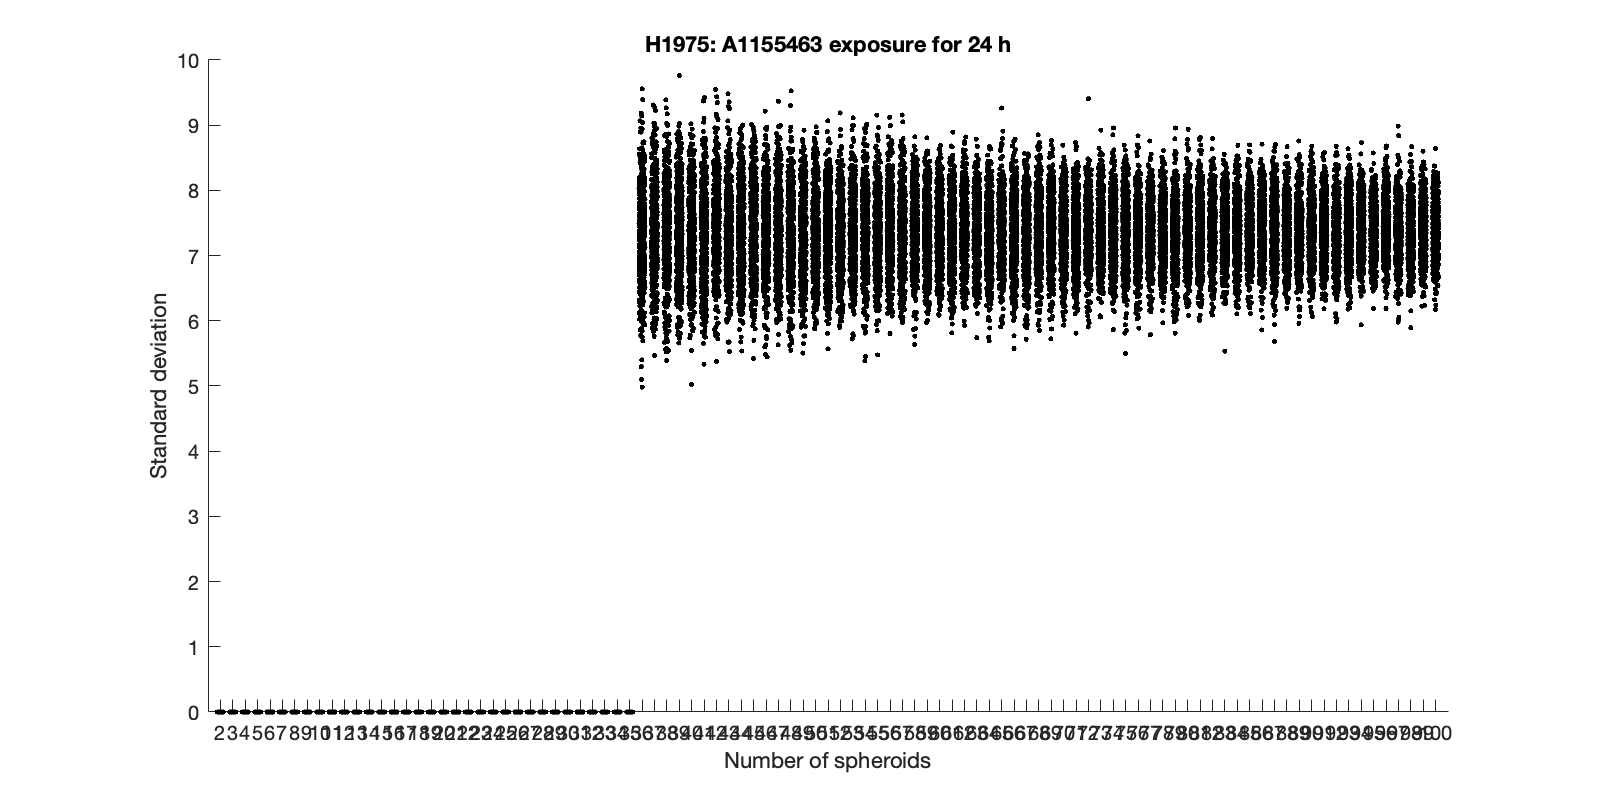

x       = 2:highNumSph; 
x0      = 10;
y0      = 10;
plotW   = 800;
plotH   = 400;


figure;
H = notBoxPlot(std_h19_24(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('H1975: A1155463 exposure for 24 h')
xlabel('Number of spheroids')
ylabel('Standard deviation')

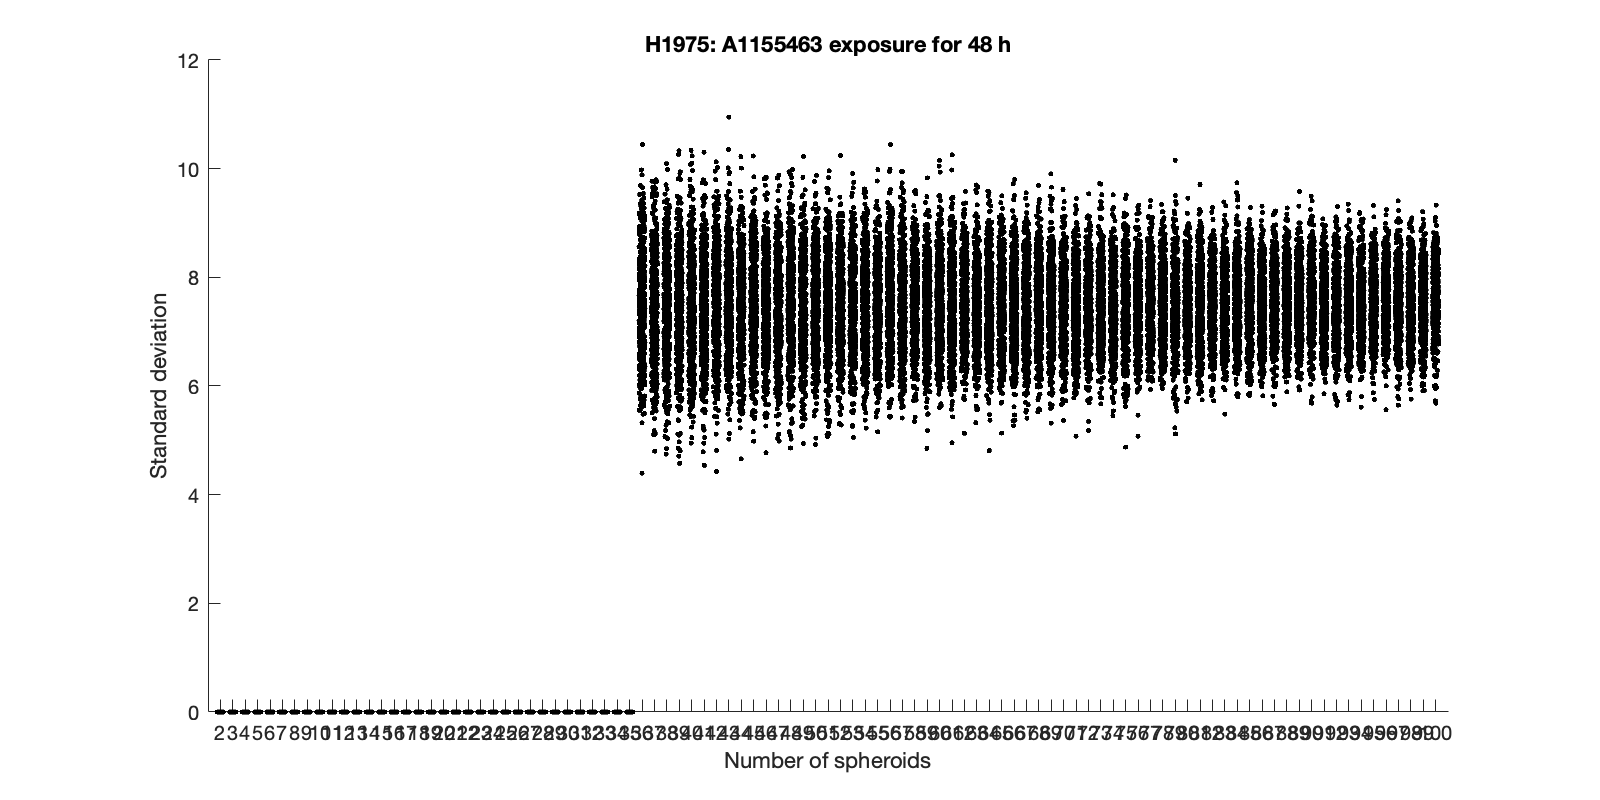


figure;
H = notBoxPlot(std_h19_48(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('H1975: A1155463 exposure for 48 h')
xlabel('Number of spheroids')
ylabel('Standard deviation')

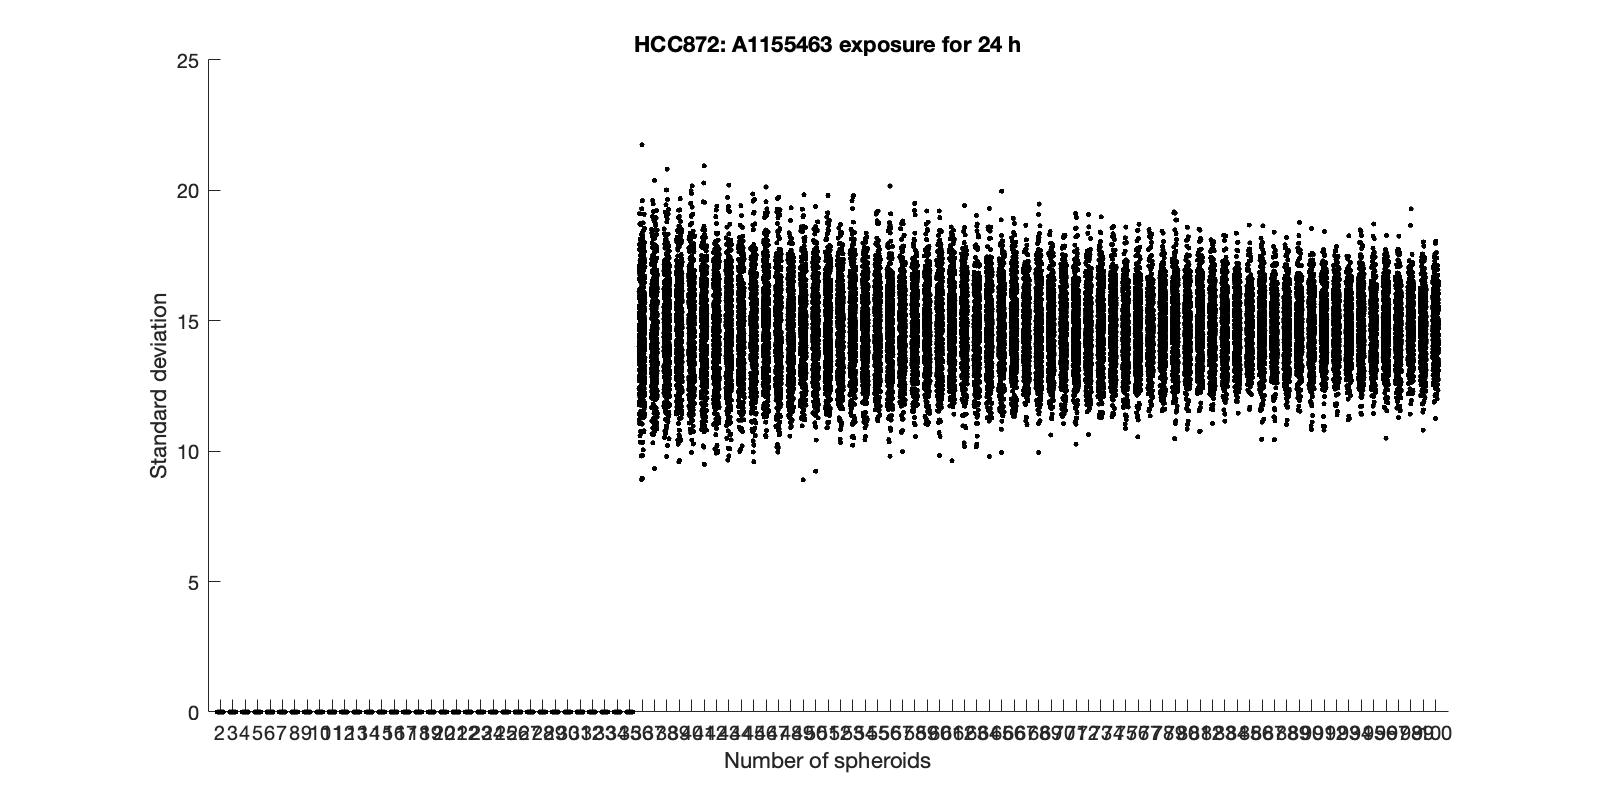

figure;
H = notBoxPlot(std_hcc_24(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('HCC872: A1155463 exposure for 24 h')
xlabel('Number of spheroids')
ylabel('Standard deviation')

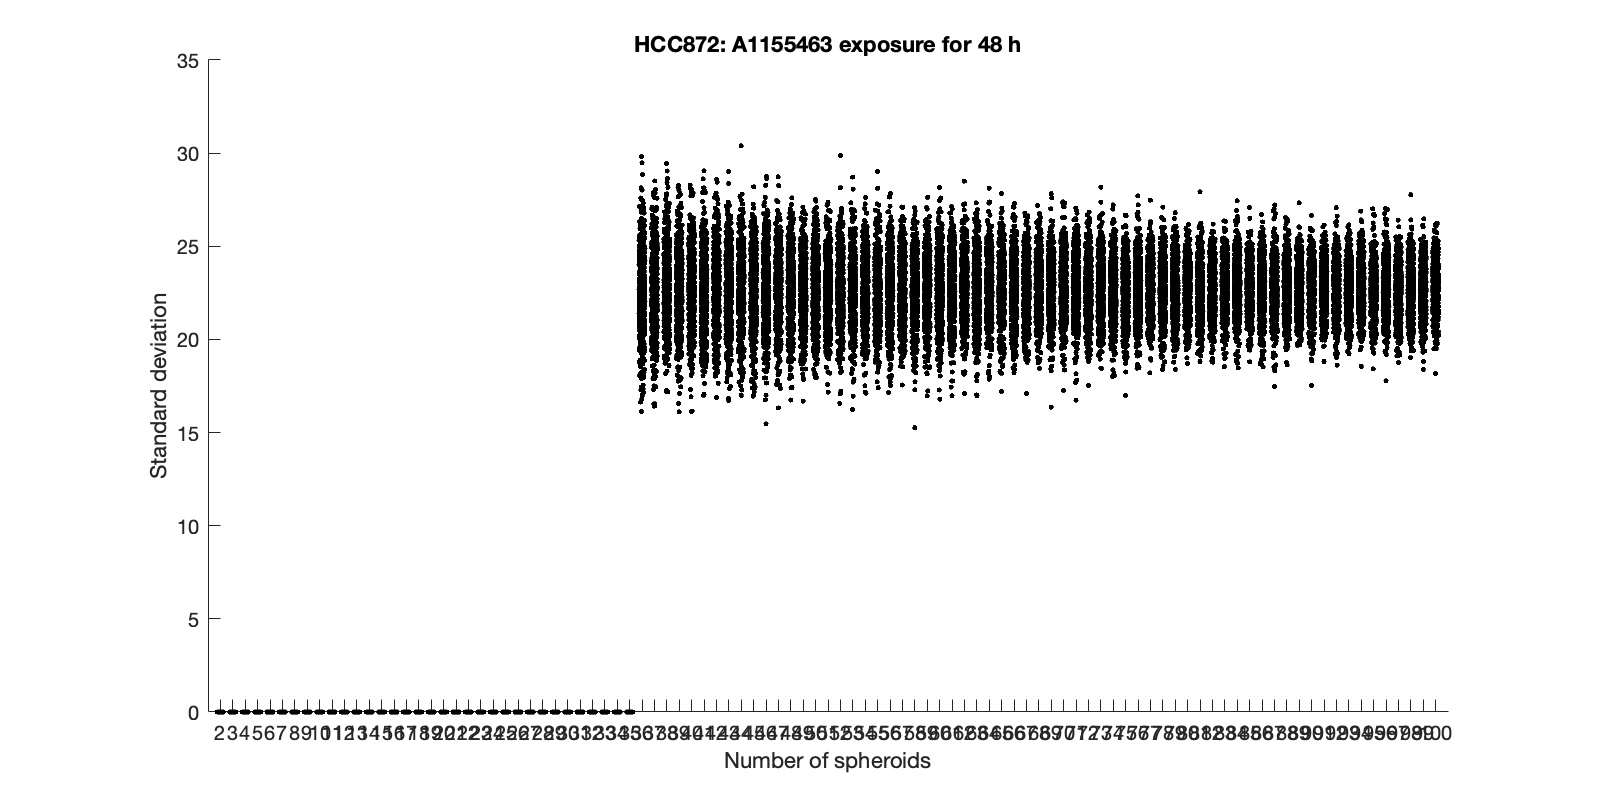


figure;
H = notBoxPlot(std_hcc_48(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('HCC872: A1155463 exposure for 48 h')
xlabel('Number of spheroids')
ylabel('Standard deviation')

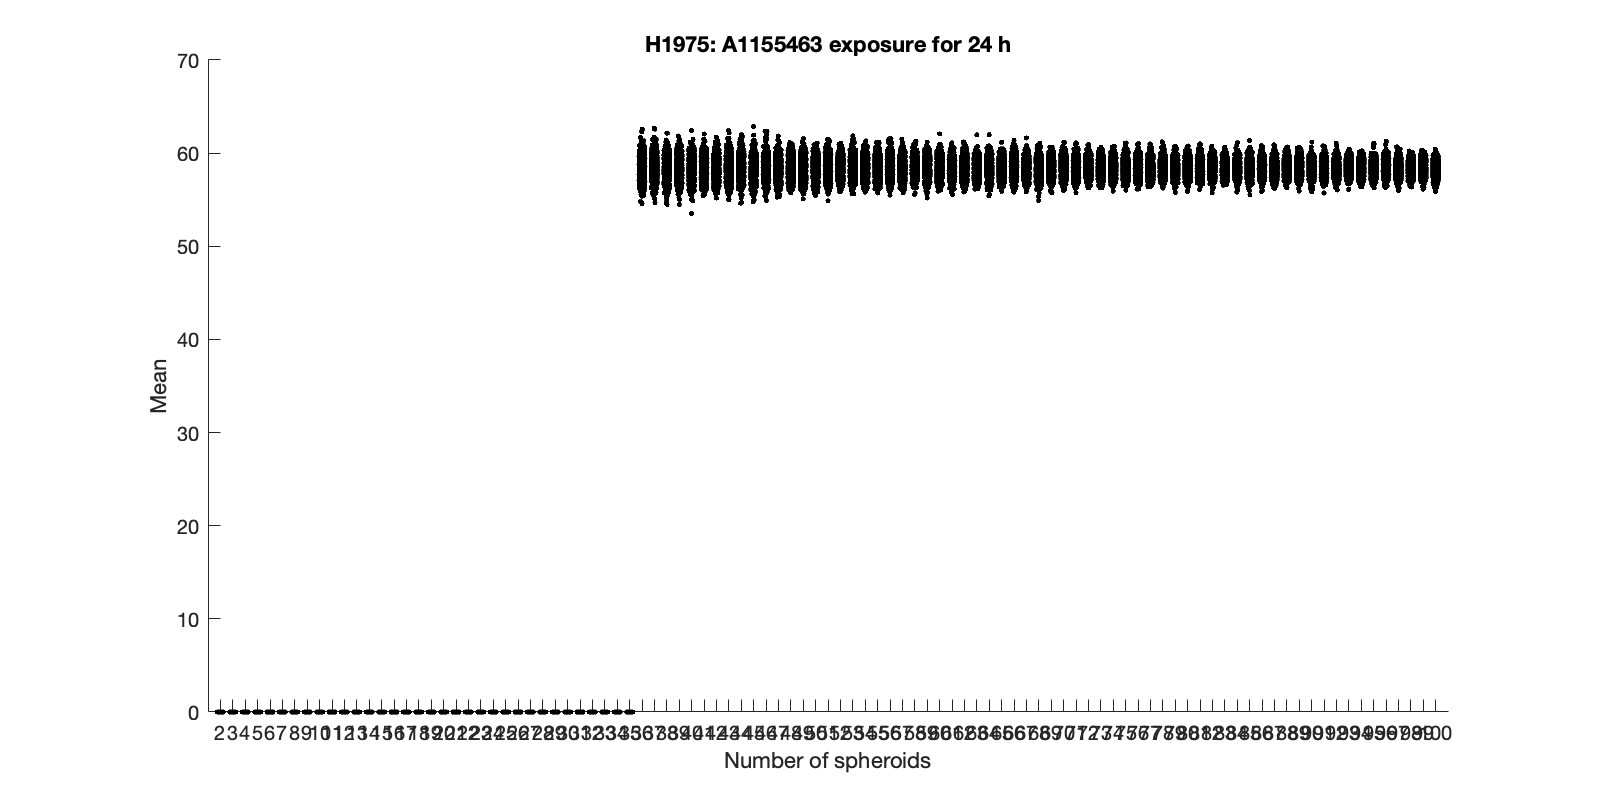

figure;
H = notBoxPlot(mean_h19_24(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('H1975: A1155463 exposure for 24 h')
xlabel('Number of spheroids')
ylabel('Mean')

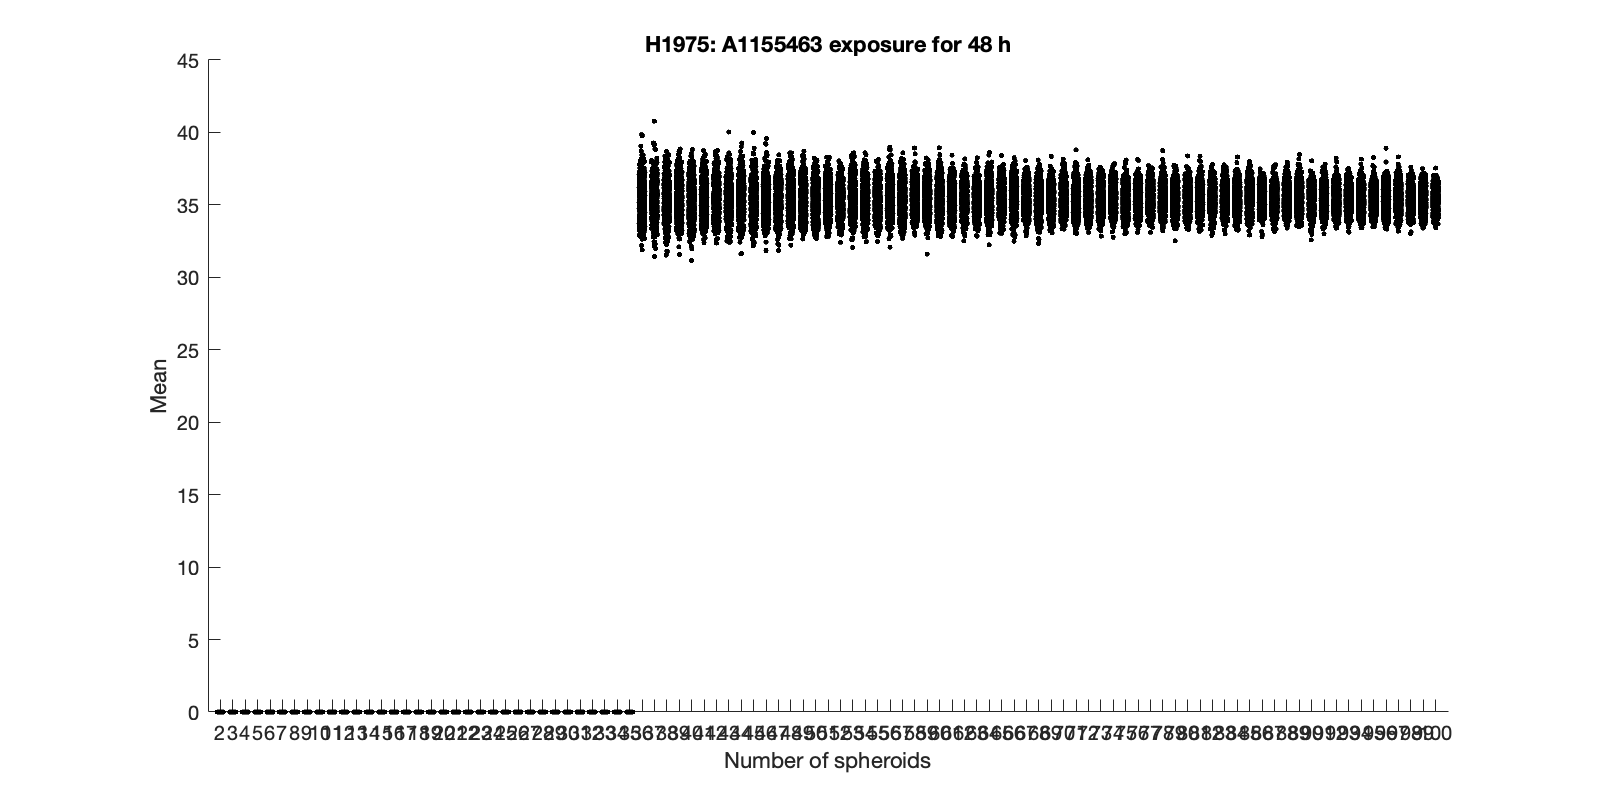


figure;
H = notBoxPlot(mean_h19_48(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('H1975: A1155463 exposure for 48 h')
xlabel('Number of spheroids')
ylabel('Mean')

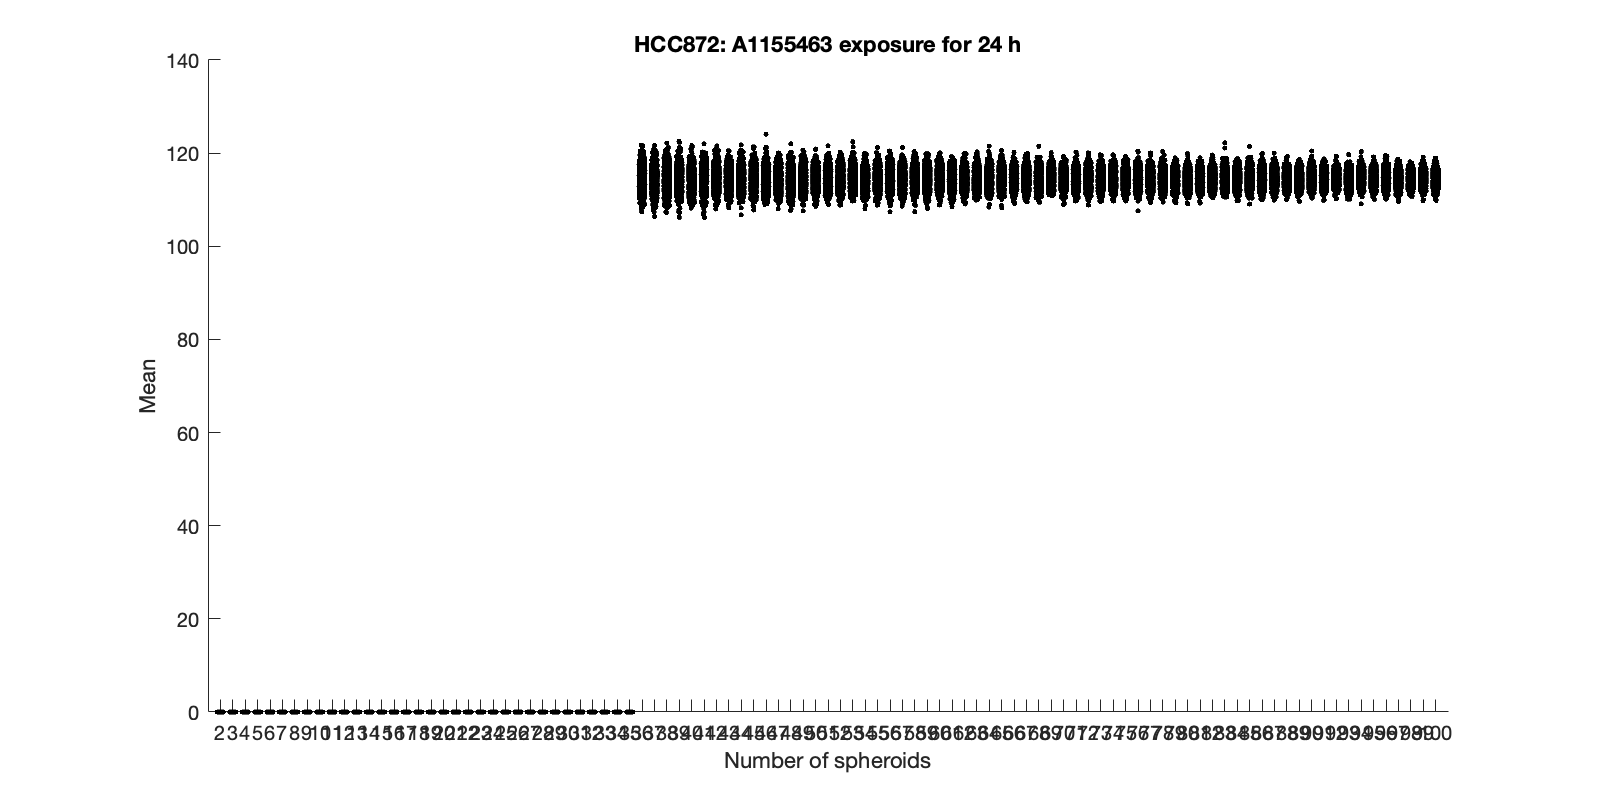


figure;
H = notBoxPlot(mean_hcc_24(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('HCC872: A1155463 exposure for 24 h')
xlabel('Number of spheroids')
ylabel('Mean')

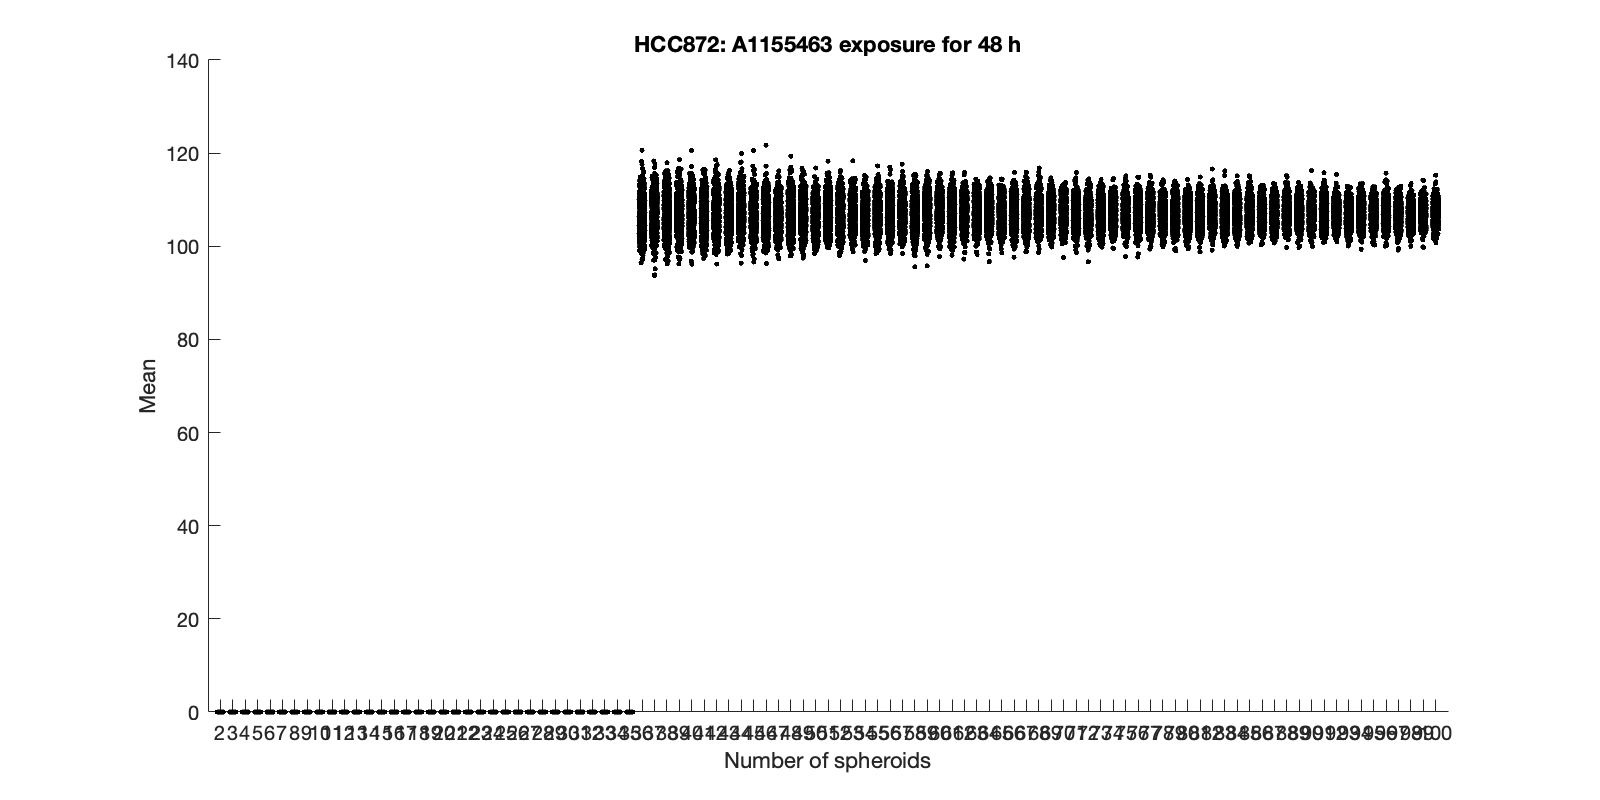


figure;
H = notBoxPlot(mean_hcc_48(2:end,:)',x);
set([H.data], 'Marker','.')
set(gcf,'position',[x0,y0,plotW,plotH])
title('HCC872: A1155463 exposure for 48 h')
xlabel('Number of spheroids')
ylabel('Mean')

Statistical analysis

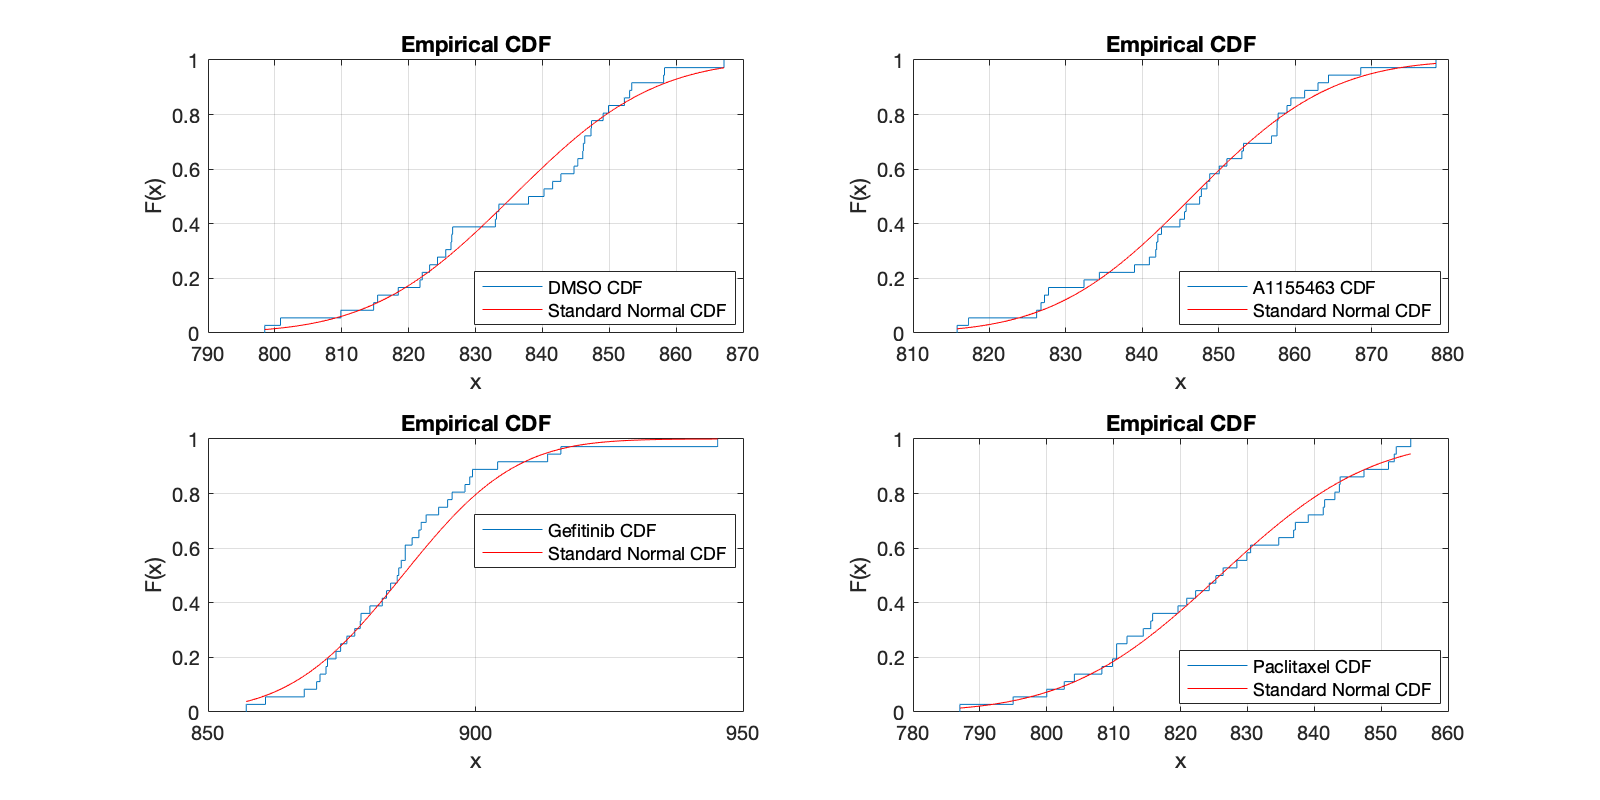

sig_dmso_a11    = [sum(p_dmso_a11<0.0001 ,2)...
                   sum(p_dmso_a11>=0.0001 & p_dmso_a11<0.001 ,2)...
                   sum(p_dmso_a11>=0.001 & p_dmso_a11<0.01 ,2)...
                   sum(p_dmso_a11>=0.01 & p_dmso_a11<0.05 ,2)...
                   sum(p_dmso_a11>=0.05 ,2)];
sig_dmso_gef    = [sum(p_dmso_gef<0.0001 ,2)...
                   sum(p_dmso_gef>=0.0001 & p_dmso_gef<0.001 ,2)...
                   sum(p_dmso_gef>=0.001 & p_dmso_gef<0.01 ,2)...
                   sum(p_dmso_gef>=0.01 & p_dmso_gef<0.05 ,2)...
                   sum(p_dmso_gef>=0.05 ,2)];
sig_dmso_pax    = [sum(p_dmso_pax<0.0001 ,2)...
                   sum(p_dmso_pax>=0.0001 & p_dmso_pax<0.001 ,2)...
                   sum(p_dmso_pax>=0.001 & p_dmso_pax<0.01 ,2)...
                   sum(p_dmso_pax>=0.01 & p_dmso_pax<0.05 ,2)...
                   sum(p_dmso_pax>=0.05 ,2)];
sig_a11_gef     = [sum(p_a11_gef<0.0001 ,2)...
                   sum(p_a11_gef>=0.0001 & p_a11_gef<0.001 ,2)...
                   sum(p_a11_gef>=0.001 & p_a11_gef<0.01 ,2)...
                   sum(p_a11_gef>=0.01 & p_a11_gef<0.05 ,2)...
                   sum(p_a11_gef>=0.05 ,2)];
sig_a11_pax     = [sum(p_a11_pax<0.0001 ,2)...
                   sum(p_a11_pax>=0.0001 & p_a11_pax<0.001 ,2)...
                   sum(p_a11_pax>=0.001 & p_a11_pax<0.01 ,2)...
                   sum(p_a11_pax>=0.01 & p_a11_pax<0.05 ,2)...
                   sum(p_a11_pax>=0.05 ,2)];
sig_gef_pax     = [sum(p_gef_pax<0.0001 ,2)...
                   sum(p_gef_pax>=0.0001 & p_gef_pax<0.001 ,2)...
                   sum(p_gef_pax>=0.001 & p_gef_pax<0.01 ,2)...
                   sum(p_gef_pax>=0.01 & p_gef_pax<0.05 ,2)...
                   sum(p_gef_pax>=0.05 ,2)];

sigt_dmso_a11   = [sum(pt_dmso_a11<0.0001 ,2)...
                   sum(pt_dmso_a11>=0.0001 & pt_dmso_a11<0.001 ,2)...
                   sum(pt_dmso_a11>=0.001 & pt_dmso_a11<0.01 ,2)...
                   sum(pt_dmso_a11>=0.01 & pt_dmso_a11<0.05 ,2)...
                   sum(pt_dmso_a11>=0.05 ,2)];
sigt_dmso_gef   = [sum(pt_dmso_gef<0.0001 ,2)...
                   sum(pt_dmso_gef>=0.0001 & pt_dmso_gef<0.001 ,2)...
                   sum(pt_dmso_gef>=0.001 & pt_dmso_gef<0.01 ,2)...
                   sum(pt_dmso_gef>=0.01 & pt_dmso_gef<0.05 ,2)...
                   sum(pt_dmso_gef>=0.05 ,2)];
sigt_dmso_pax   = [sum(pt_dmso_pax<0.0001 ,2)...
                   sum(pt_dmso_pax>=0.0001 & pt_dmso_pax<0.001 ,2)...
                   sum(pt_dmso_pax>=0.001 & pt_dmso_pax<0.01 ,2)...
                   sum(pt_dmso_pax>=0.01 & pt_dmso_pax<0.05 ,2)...
                   sum(pt_dmso_pax>=0.05 ,2)];

sig_4_7         = [sum(pt_4_7<0.0001 ,2)...
                   sum(pt_4_7>=0.0001 & pt_4_7<0.001 ,2)...
                   sum(pt_4_7>=0.001 & pt_4_7<0.01 ,2)...
                   sum(pt_4_7>=0.01 & pt_4_7<0.05 ,2)...
                   sum(pt_4_7>=0.05 ,2)];
sig_8_9         = [sum(pt_8_9<0.0001 ,2)...
                   sum(pt_8_9>=0.0001 & pt_8_9<0.001 ,2)...
                   sum(pt_8_9>=0.001 & pt_8_9<0.01 ,2)...
                   sum(pt_8_9>=0.01 & pt_8_9<0.05 ,2)...
                   sum(pt_8_9>=0.05 ,2)];
sig_2_14        = [sum(pt_2_14<0.0001 ,2)...
                   sum(pt_2_14>=0.0001 & pt_2_14<0.001 ,2)...
                   sum(pt_2_14>=0.001 & pt_2_14<0.01 ,2)...
                   sum(pt_2_14>=0.01 & pt_2_14<0.05 ,2)...
                   sum(pt_2_14>=0.05 ,2)];
sig_12_15       = [sum(pt_12_15<0.0001 ,2)...
                   sum(pt_12_15>=0.0001 & pt_12_15<0.001 ,2)...
                   sum(pt_12_15>=0.001 & pt_12_15<0.01 ,2)...
                   sum(pt_12_15>=0.01 & pt_12_15<0.05 ,2)...
                   sum(pt_12_15>=0.05 ,2)];
sig_3_10        = [sum(pt_3_10<0.0001 ,2)...
                   sum(pt_3_10>=0.0001 & pt_3_10<0.001 ,2)...
                   sum(pt_3_10>=0.001 & pt_3_10<0.01 ,2)...
                   sum(pt_3_10>=0.01 & pt_3_10<0.05 ,2)...
                   sum(pt_3_10>=0.05 ,2)];
sig_1_16        = [sum(pt_1_16<0.0001 ,2)...
                   sum(pt_1_16>=0.0001 & pt_1_16<0.001 ,2)...
                   sum(pt_1_16>=0.001 & pt_1_16<0.01 ,2)...
                   sum(pt_1_16>=0.01 & pt_1_16<0.05 ,2)...
                   sum(pt_1_16>=0.05 ,2)];

sigTub_33_24    = [sum(ptub_33_24<0.0001 ,2)...
                   sum(ptub_33_24>=0.0001 & ptub_33_24<0.001 ,2)...
                   sum(ptub_33_24>=0.001 & ptub_33_24<0.01 ,2)...
                   sum(ptub_33_24>=0.01 & ptub_33_24<0.05 ,2)...
                   sum(ptub_33_24>=0.05 ,2)];
sigTub_23_14    = [sum(ptub_23_14<0.0001 ,2)...
                   sum(ptub_23_14>=0.0001 & ptub_23_14<0.001 ,2)...
                   sum(ptub_23_14>=0.001 & ptub_23_14<0.01 ,2)...
                   sum(ptub_23_14>=0.01 & ptub_23_14<0.05 ,2)...
                   sum(ptub_23_14>=0.05 ,2)];
sigTub_33_43    = [sum(ptub_33_43<0.0001 ,2)...
                   sum(ptub_33_43>=0.0001 & ptub_33_43<0.001 ,2)...
                   sum(ptub_33_43>=0.001 & ptub_33_43<0.01 ,2)...
                   sum(ptub_33_43>=0.01 & ptub_33_43<0.05 ,2)...
                   sum(ptub_33_43>=0.05 ,2)];
sigTub_33_34    = [sum(ptub_33_34<0.0001 ,2)...
                   sum(ptub_33_34>=0.0001 & ptub_33_34<0.001 ,2)...
                   sum(ptub_33_34>=0.001 & ptub_33_34<0.01 ,2)...
                   sum(ptub_33_34>=0.01 & ptub_33_34<0.05 ,2)...
                   sum(ptub_33_34>=0.05 ,2)];
sigTub_23_24    = [sum(ptub_23_24<0.0001 ,2)...
                   sum(ptub_23_24>=0.0001 & ptub_23_24<0.001 ,2)...
                   sum(ptub_23_24>=0.001 & ptub_23_24<0.01 ,2)...
                   sum(ptub_23_24>=0.01 & ptub_23_24<0.05 ,2)...
                   sum(ptub_23_24>=0.05 ,2)];
sigTub_43_44    = [sum(ptub_43_44<0.0001 ,2)...
                   sum(ptub_43_44>=0.0001 & ptub_43_44<0.001 ,2)...
                   sum(ptub_43_44>=0.001 & ptub_43_44<0.01 ,2)...
                   sum(ptub_43_44>=0.01 & ptub_43_44<0.05 ,2)...
                   sum(ptub_43_44>=0.05 ,2)];

sigTub_11_12    = [sum(ptub_11_12<0.0001 ,2)...
                   sum(ptub_11_12>=0.0001 & ptub_11_12<0.001 ,2)...
                   sum(ptub_11_12>=0.001 & ptub_11_12<0.01 ,2)...
                   sum(ptub_11_12>=0.01 & ptub_11_12<0.05 ,2)...
                   sum(ptub_11_12>=0.05 ,2)];
sigTub_11_21    = [sum(ptub_11_21<0.0001 ,2)...
                   sum(ptub_11_21>=0.0001 & ptub_11_21<0.001 ,2)...
                   sum(ptub_11_21>=0.001 & ptub_11_21<0.01 ,2)...
                   sum(ptub_11_21>=0.01 & ptub_11_21<0.05 ,2)...
                   sum(ptub_11_21>=0.05 ,2)];
sigTub_11_22    = [sum(ptub_11_22<0.0001 ,2)...
                   sum(ptub_11_22>=0.0001 & ptub_11_22<0.001 ,2)...
                   sum(ptub_11_22>=0.001 & ptub_11_22<0.01 ,2)...
                   sum(ptub_11_22>=0.01 & ptub_11_22<0.05 ,2)...
                   sum(ptub_11_22>=0.05 ,2)];
sigTub_22_33    = [sum(ptub_22_33<0.0001 ,2)...
                   sum(ptub_22_33>=0.0001 & ptub_22_33<0.001 ,2)...
                   sum(ptub_22_33>=0.001 & ptub_22_33<0.01 ,2)...
                   sum(ptub_22_33>=0.01 & ptub_22_33<0.05 ,2)...
                   sum(ptub_22_33>=0.05 ,2)];
sigTub_11_33    = [sum(ptub_11_33<0.0001 ,2)...
                   sum(ptub_11_33>=0.0001 & ptub_11_33<0.001 ,2)...
                   sum(ptub_11_33>=0.001 & ptub_11_33<0.01 ,2)...
                   sum(ptub_11_33>=0.01 & ptub_11_33<0.05 ,2)...
                   sum(ptub_11_33>=0.05 ,2)];
sigTub_23_33    = [sum(ptub_23_33<0.0001 ,2)...
                   sum(ptub_23_33>=0.0001 & ptub_23_33<0.001 ,2)...
                   sum(ptub_23_33>=0.001 & ptub_23_33<0.01 ,2)...
                   sum(ptub_23_33>=0.01 & ptub_23_33<0.05 ,2)...
                   sum(ptub_23_33>=0.05 ,2)];
sigTub_21_22    = [sum(ptub_21_22<0.0001 ,2)...
                   sum(ptub_21_22>=0.0001 & ptub_21_22<0.001 ,2)...
                   sum(ptub_21_22>=0.001 & ptub_21_22<0.01 ,2)...
                   sum(ptub_21_22>=0.01 & ptub_21_22<0.05 ,2)...
                   sum(ptub_21_22>=0.05 ,2)];



sig_ANOVA       = [sum(pAnova<0.0001 ,2)...
                   sum(pAnova>=0.0001 & pAnova<0.001 ,2)...
                   sum(pAnova>=0.001 & pAnova<0.01 ,2)...
                   sum(pAnova>=0.01 & pAnova<0.05 ,2)...
                   sum(pAnova>=0.05 ,2)];

x               = lowNumSph:highNumSph;

testStr     = 'ANOVA';
postHocStr  = 'Dunnets';
cellLineStr = 'HCC872';


figure,
subplot(2,2,1)
cdfplot(ovc_dmso)
hold on
x_values = linspace(min(ovc_dmso),max(ovc_dmso));
plot(x_values,normcdf(x_values, mean(ovc_dmso),std(ovc_dmso)),'r-')
legend('DMSO CDF','Standard Normal CDF','Location','best')
hold off
subplot(2,2,2)
cdfplot(ovc_a11)
hold on
x_values = linspace(min(ovc_a11),max(ovc_a11));
plot(x_values,normcdf(x_values, mean(ovc_a11),std(ovc_a11)),'r-')
legend('A1155463 CDF','Standard Normal CDF','Location','best')
hold off
subplot(2,2,3)
cdfplot(ovc_gef)
hold on
x_values = linspace(min(ovc_gef),max(ovc_gef));
plot(x_values,normcdf(x_values, mean(ovc_gef),std(ovc_gef)),'r-')
legend('Gefitinib CDF','Standard Normal CDF','Location','best')
hold off
subplot(2,2,4)
cdfplot(ovc_pax)
hold on
x_values = linspace(min(ovc_pax),max(ovc_pax));
plot(x_values,normcdf(x_values, mean(ovc_pax),std(ovc_pax)),'r-')
legend('Paclitaxel CDF','Standard Normal CDF','Location','best')
hold off
set(gcf,'position',[x0,y0,plotW,plotH])

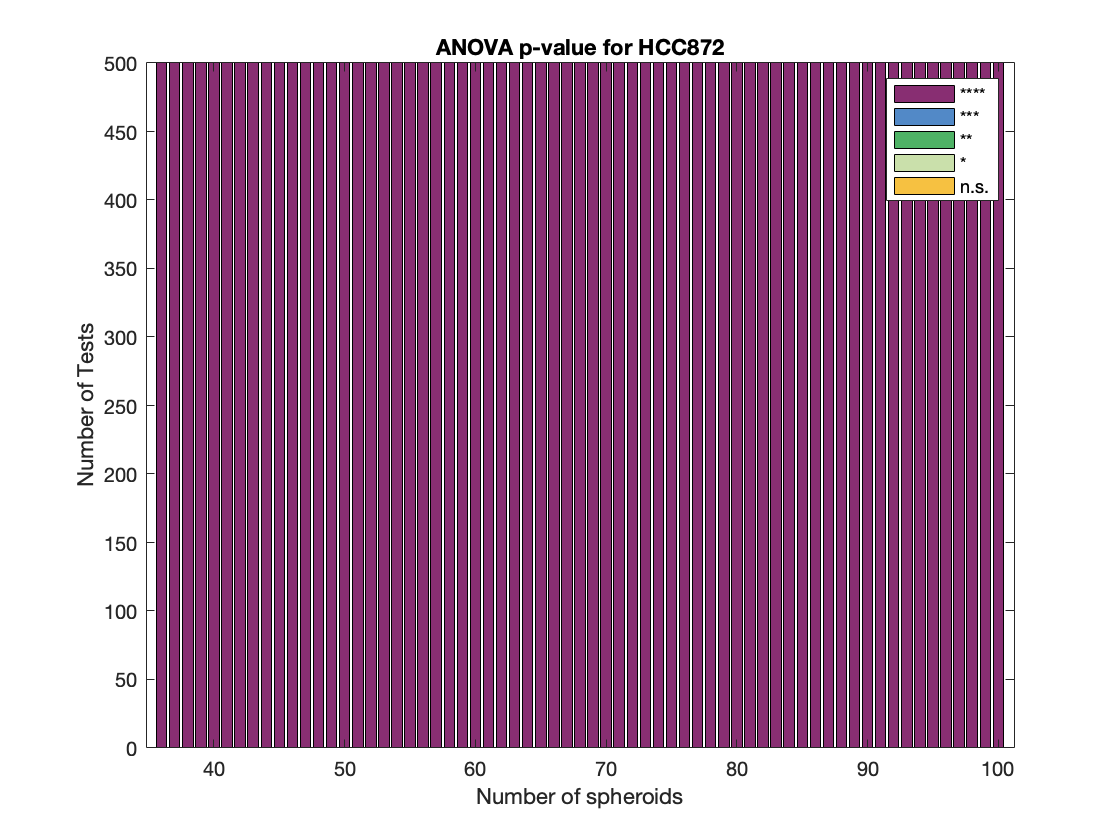





figure,
b = bar(x, sig_ANOVA(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title([testStr ' p-value for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')

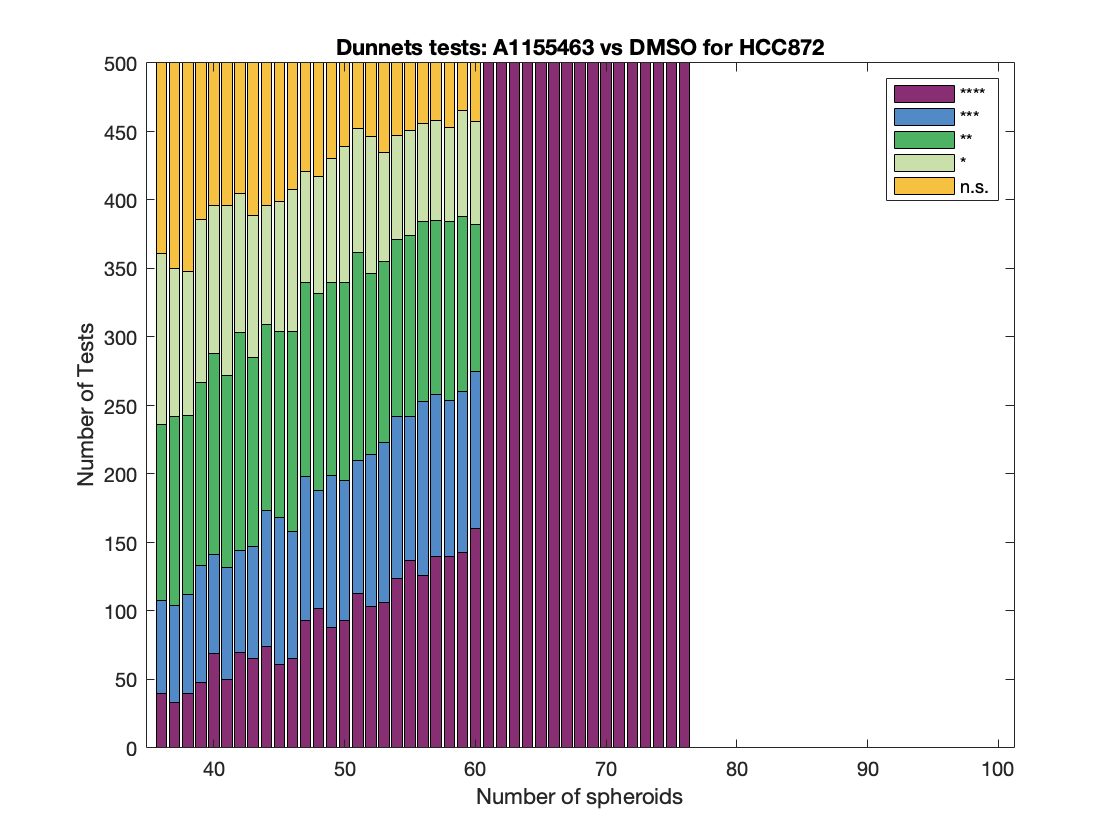


figure,
b = bar(x, sig_dmso_a11(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title([postHocStr ' tests: A1155463 vs DMSO for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')

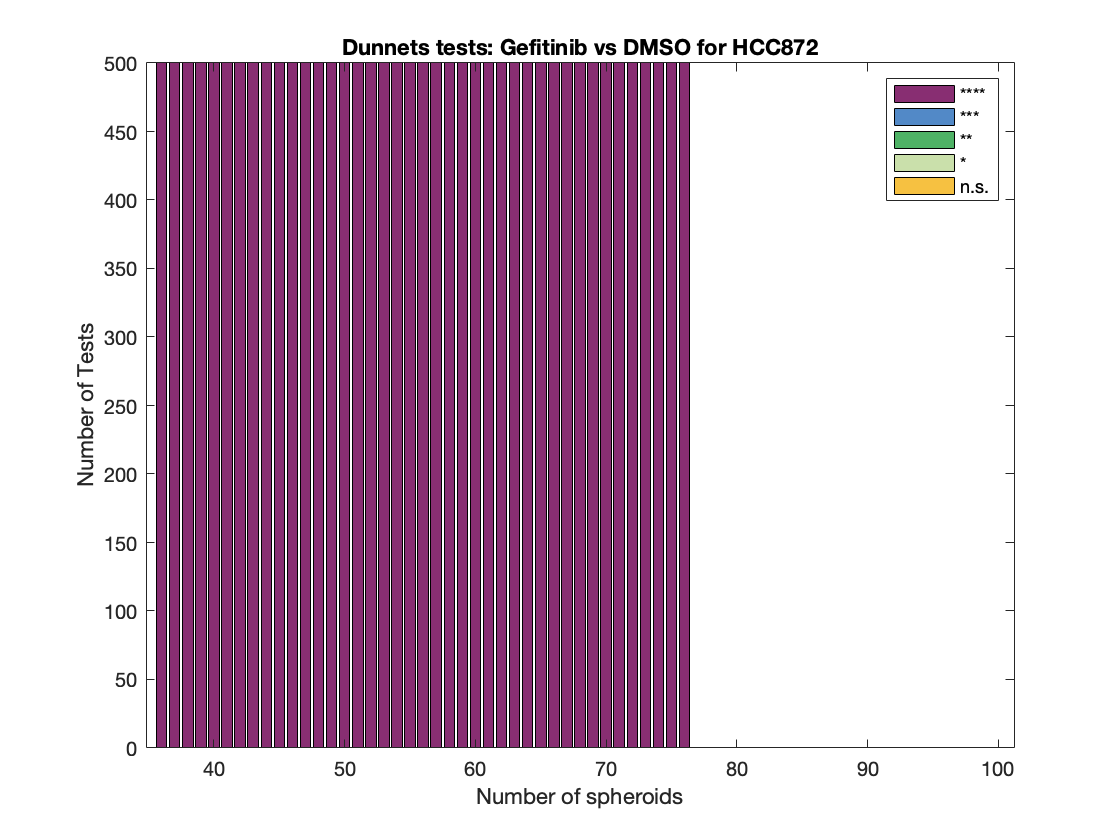

figure,
b = bar(x, sig_dmso_gef(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title([postHocStr ' tests: Gefitinib vs DMSO for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')

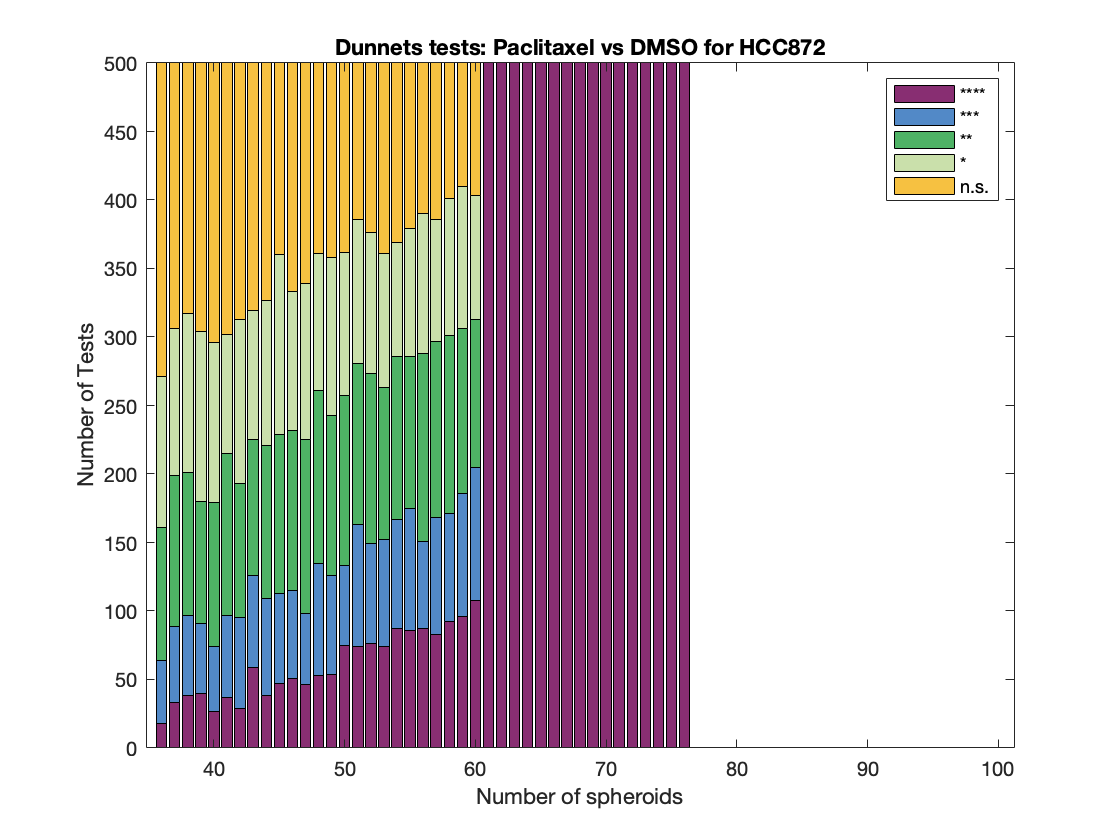


figure,
b = bar(x, sig_dmso_pax(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title([postHocStr ' tests: Paclitaxel vs DMSO for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')

figure,
b = bar(x, sig_a11_gef(lowNumSph:highNumSph,:),'stacked');

Index in position 1 exceeds array bounds (must not exceed 36).

b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
set(gcf,'position',[x0,y0,plotW,plotH])
title([postHocStr ' tests: A1155463 vs Gefitinib for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
figure,
b = bar(x, sig_a11_pax(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
set(gcf,'position',[x0,y0,plotW,plotH])
title([postHocStr ' tests: A1155463 vs Paclitaxel for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
figure,
b = bar(x, sig_gef_pax(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
set(gcf,'position',[x0,y0,plotW,plotH])
title([postHocStr ' tests: Gefitinib vs Paclitaxel for ' cellLineStr])
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
figure,
b = bar(x, sigt_dmso_a11(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: A1155463 vs DMSO for OVCAR8')
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')

figure,
b = bar(x, sigt_dmso_gef(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: Gefitinib vs DMSO for OVCAR8')
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')

figure,
b = bar(x, sigt_dmso_pax(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: Paclitaxel vs DMSO for OVCAR8')
xlabel('Number of spheroids')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
figure,
set(gcf,'position',[x0,y0,plotW,800])
subplot(3,2,1)
b = bar(x, sig_1_16(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 1 vs 16 for A498-RFP')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,2)
b = bar(x, sig_3_10(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 3 vs 10 for A498-RFP')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,3)
b = bar(x, sig_12_15(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 12 vs 15 for A498-RFP')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,4)
b = bar(x, sig_2_14(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 2 vs 14 for A498-RFP')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,5)
b = bar(x, sig_8_9(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 8 vs 9 for A498-RFP')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,6)
b = bar(x, sig_4_7(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 4 vs 7 for A498-RFP')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
figure,
set(gcf,'position',[x0,y0,plotW,800])
subplot(3,2,1)
b = bar(x, sigTub_33_24(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 3,2 vs 4,2 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,3)
b = bar(x, sigTub_23_14(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 2,3 vs 1,4 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,5)
b = bar(x, sigTub_33_43(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 3,1 vs 4,1 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,2)
b = bar(x, sigTub_23_24(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 2,3 vs 2,4 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,4)
b = bar(x, sigTub_33_34(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 3,3 vs 3,4 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
subplot(3,2,6)
b = bar(x, sigTub_43_44(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 4,3 vs 4,4 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.')
figure,
set(gcf,'position',[x0,y0,plotW,800])
subplot(3,2,1)
b = bar(x, sigTub_11_12(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 1,1 vs 1,2 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"best")
subplot(3,2,3)
b = bar(x, sigTub_11_21(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 1,1 vs 2,1 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"best")
subplot(3,2,5)
b = bar(x, sigTub_11_22(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 1,1 vs 2,2 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"best")
subplot(3,2,2)
b = bar(x, sigTub_22_33(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 3,3 vs 2,2 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"best")
subplot(3,2,4)
b = bar(x, sigTub_11_33(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 3,3 vs 1,1 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"best")
subplot(3,2,6)
b = bar(x, sigTub_23_33(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 2,1 vs 2,2 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"best")
figure,
b = bar(x, sigTub_11_21(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 1,1 vs 2,1 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"southeast")
figure,
b = bar(x, sigTub_21_22(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 2,1 vs 2,2 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"southeast")
figure,
b = bar(x, sigTub_22_33(lowNumSph:highNumSph,:),'stacked');
b(1).FaceColor  = [136 46 114]./255;
b(2).FaceColor  = [82 137 199]./255;
b(3).FaceColor  = [78 178 101]./255;
b(4).FaceColor  = [202 224 171]./255;
b(5).FaceColor  = [246 193 65]./255;
%set(gcf,'position',[x0,y0,plotW,plotH])
title('T-tests: 2,2 vs 3,3 tubulin staining')
xlabel('Number of wells')
ylabel('Number of Tests')
legend('****', '***', '**', '*', 'n.s.', 'Location',"southeast")